# Getting amplitude, power and power density from a FFT

[Understanding Power Spectral Density and the Power Spectrum](https://www.youtube.com/watch?v=pfjiwxhqd1M&list=PLJhXDXp_HgwJhwHtpUraSKWFdEQEM73OO&index=28)

## Creating time signal

fs = 500;
t = 0:1/fs:5-1/fs;
freq = 0:fs/length(t):fs-1/fs;

A = [1 4];
f = [100; 110];

xn = A*sin(2*pi*f*t);
N = length(xn);

## Amplitude Spectrum from FFT


$$A = \frac{fft}{N}$$


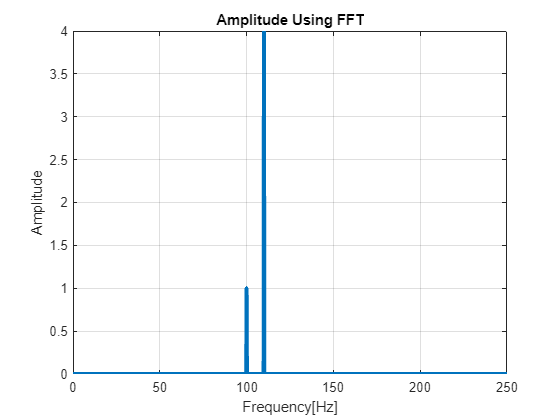

xk = abs(fft(xn))/N; %Two-sided amplitude
xk = xk(1:N/2+1); %One-sided
xk(2:end-1) = 2*xk(2:end-1); %Double values wxcept for DC and Nyquist

figure
plot(freq(1:N/2+1), xk, 'LineWidth',3)
grid on
title('Amplitude Using FFT')
xlabel('Frequency[Hz]')
ylabel('Amplitude')

## Power Spectrum from FFT - more suitable for discrete spectra (few freqs.)


$$PS = \frac{{fft}^2}{N^2}$$


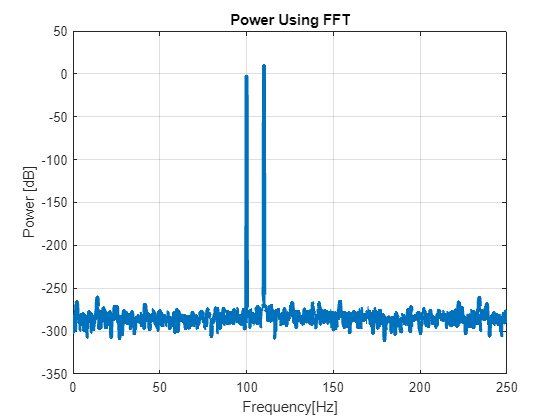

xk = abs(fft(xn)).^2/N^2;
xk = xk(1:N/2+1); %One-sided
xk(2:end-1) = 2*xk(2:end-1); %Double values wxcept for DC and Nyquist

figure
plot(freq(1:N/2+1), pow2db(xk), 'LineWidth',3)
grid on
title('Power Using FFT')
xlabel('Frequency[Hz]')
ylabel('Power [dB]')

### same - using $\it{periodogram}$

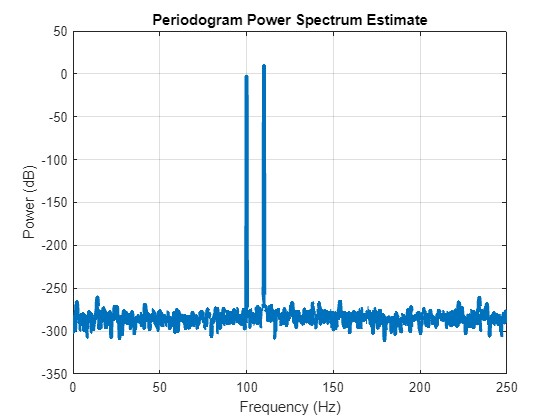

periodogram(xn, rectwin(length(xn)), length(xn), fs, 'power')
set(findall(groot, 'type', 'line'), 'Linewidth', 3)

## Power Spectral Desity from the FFT - more suitable for continuous spectra (white noise)

$PSD = PS\cdot \frac{N}{f_s}$ - for rectangular window

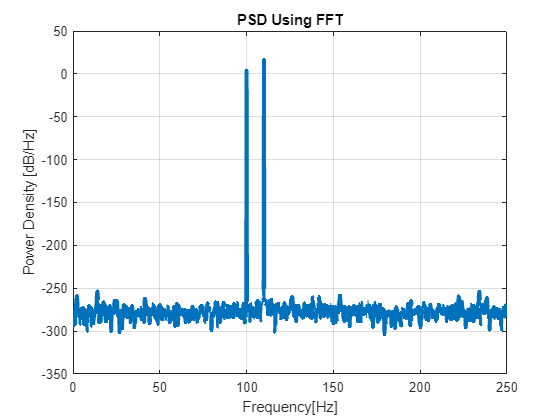

xk = abs(fft(xn)).^2/(N*fs); 
xk = xk(1:N/2+1); %One-sided
xk(2:end-1) = 2*xk(2:end-1); %Double values wxcept for DC and Nyquist

figure
plot(freq(1:N/2+1), pow2db(xk), 'LineWidth',3)
grid on
title('PSD Using FFT')
xlabel('Frequency[Hz]')
ylabel('Power Density [dB/Hz]')

### same - using $\it{periodogram}$

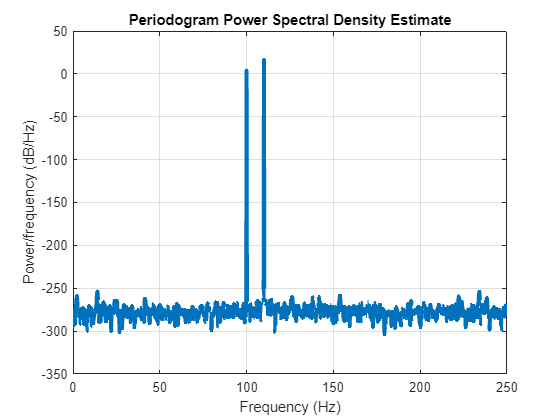

periodogram(xn, rectwin(length(xn)), length(xn), fs, 'psd')
set(findall(groot, 'type', 'line'), 'Linewidth', 3)